インフロー比較

1214など

PF39

%%なぜかfigureが出力できないので、main_pcb.mへ移行

%%ファイルへのパスを作る

%それぞれのPCから共有フォルダまでのパスはそれぞれ異なるので各自で設定
%%%%(1)spread sheetから ログのテーブルを取得してTに格納
DOCID='1wG5fBaiQ7-jOzOI-2pkPAeV6SDiHc_LrOdcbWlvhHBw';%スプレッドシートのID


T=getTS6log(DOCID);

%%%%%ここが各PCのパス
%環境変数を設定していない場合はパスを全て記入する
pathname.ts3u=getenv('ts3u_path');%old-koalaのts-3uまでのパス（mrdなど）
pathname.fourier=getenv('fourier_path');%fourierのmd0（データックのショットが入ってる）までのpath
pathname.NIFS=getenv('NIFS_path');%resultsまでのpath（ドップラー、SXR）
pathname.save=getenv('save_path'); %保存先

%  node='date';  % 検索する列の名前. T.Properties.VariableNamesで一覧表示できる
%  pat=211217;   % 検索パターン（数値なら一致検索、文字なら含む検索）　

% searchlog(T,node,pat)% ログのテーブルから当てはまるものを抽出した新しいテーブルを作成
%IDXlist=[2458:2949]
IDXlist=2925

IDXlist = 2925

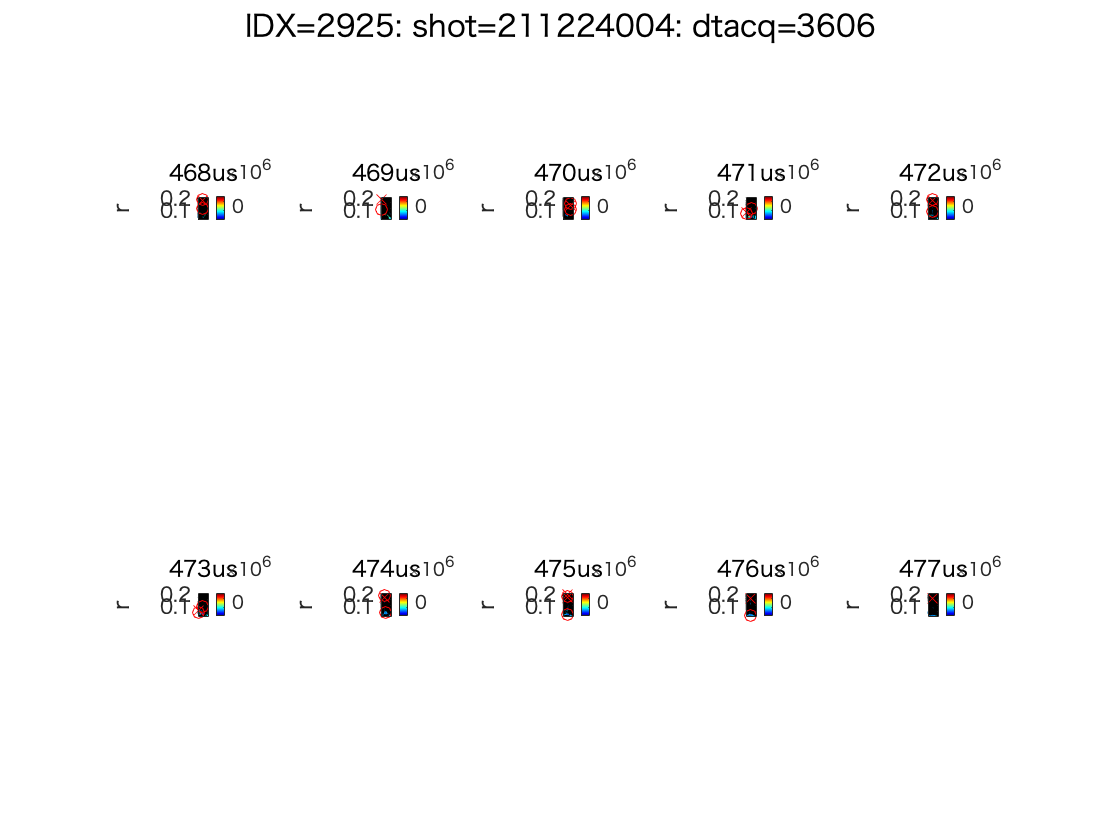

for IDX=IDXlist(1,1)
plot_psi(T, pathname,IDX)
end

function [date, shot, TF_shot, offset_TF, i_EF,start,Doppler_t, d_tacq,d_tacqTF,trange,t,n] = getinput(T,IDX)
%出力は構造体に変更しても良い
date=T.date(IDX);
shot=T.shot(IDX);
TF_shot=T.TFoffset(IDX);
offset_TF=isfinite(TF_shot);

d_tacq=T.d_tacq(IDX);
d_tacqTF=T.TFdtacq(IDX);
if isnan(T.EF_A_(IDX))%%NaNでないことを確認（ログが空白だとNaNになる）
    i_EF=150;
else  %NaNなら150をとりあえず代入、記入されているときはその値を使う
    i_EF=T.EF_A_(IDX);
end
trange=460:490;
t=T.DopplerDelay(IDX);
n=30;

start=T.Period_StartTime_(IDX);
Doppler_t=T.DopplerDelay(IDX);
end

function plot_psi(T, pathname,IDX)
[date, shot, TF_shot, offset_TF, i_EF,start,Doppler_t, d_tacq,d_tacqTF,trange,t,n] = getinput(T,IDX);%Tのテーブルから入力のリストを出力

%%磁気プローブデータ全体）
[grid2D, data2D] = pcbdata(date, d_tacq,d_tacqTF,trange, [], n,i_EF);

if isstruct(grid2D)==0 %もしdtacqデータがない場合次のloopへ(データがない場合NaNを返しているため)
    return
end
    maxrange=max(abs(data2D.Jt),[],'all');

%%%midplaneとかO点、X点を探す
[psimid,mid]=min(data2D.psi,[],2);
[opoint,p]=islocalmin(psimid,1);
[xpoint,~]=islocalmax(psimid,1);
[xp_psi,maxxp]=max(squeeze(psimid),[],1);
% onum=squeeze(sum(opoint,1));
% trange(onum~=0)
    %maxrange=2e6;

%%磁気面時間発展プロット
figure
 start=8; %460+?
 for m=1:10 
     i=start+m;
     t=trange(i);
     subplot(2,5,m)
    contourf(grid2D.zq(1,:),grid2D.rq(:,1),data2D.Jt(:,:,i),10,'LineStyle','none')
    colormap(jet)
    axis image
    axis tight manual
    %     xlim([-0.02 0.02])
    %     ylim([0.12 0.27])
%     caxis([-maxrange,maxrange])
    caxis([-3*1e+6,3*1e+6])
    colorbar('Location','eastoutside')
    %zlim([-1 1])
    %colormap(bone)
    hold on
    plot(grid2D.zq(1,squeeze(mid(:,:,i))),grid2D.rq(:,1))
    contour(grid2D.zq(1,:),grid2D.rq(:,1),squeeze(data2D.psi(:,:,i)),50,'black')
    plot(grid2D.zq(1,squeeze(mid(opoint(:,:,i),:,i))),grid2D.rq(opoint(:,:,i),1),"ro")
    plot(grid2D.zq(1,squeeze(mid(xpoint(:,:,i),:,i))),grid2D.rq(xpoint(:,:,i),1),"rx")
    hold off
    title(string(t)+'us')
    xlabel('z')
    ylabel('r')
end

sgtitle(strcat('IDX=',num2str(IDX),': shot=',num2str(date),num2str(shot,'%03i'),': dtacq=',num2str(T.d_tacq(IDX))))

%saveas(gcf,strcat(pathname.save,'\IDX',num2str(IDX),'_shot',num2str(date),num2str(shot,'%03i'),'_dtacq',num2str(T.d_tacq(IDX)),'_cr',num2str(cr_time),'us.png'))
%save(strcat(pathname.save,'\IDX',num2str(IDX),'_shot',num2str(date),num2str(shot,'%03i'),'_dtacq',num2str(T.d_tacq(IDX)),'_cr',num2str(cr_time),'us.mat')
% close
end